# Create Deep Learning Network Architecture with Pretrained Parameters

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `layers`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 27-Apr-2024 10:43:08

## Load Network Parameters

Load network parameters like weights, biases, or layers unusupported for network code generation from the the stored parameters file.

params = load("C:\Users\iamal\Desktop\CIFAR10 Project\params_2024_04_27__10_43_00.mat");

## Create Array of Layers

layers = [
    imageInputLayer([28 28 3],"Name","imageinput")
    convolution2dLayer([3 3],32,"Name","conv","Padding",[1 1 1 1])
    reluLayer("Name","relu")
    batchNormalizationLayer("Name","batchnorm")
    convolution2dLayer([3 3],64,"Name","conv_1","Padding",[1 1 1 1],"Stride",[2 2])
    reluLayer("Name","relu_1")
    batchNormalizationLayer("Name","batchnorm_1")
    convolution2dLayer([3 3],128,"Name","conv_3","Padding",[1 1 1 1])
    reluLayer("Name","relu_3")
    batchNormalizationLayer("Name","batchnorm_3")
    convolution2dLayer([3 3],256,"Name","conv_2","Padding",[1 1 1 1])
    reluLayer("Name","relu_2")
    batchNormalizationLayer("Name","batchnorm_2")
    dropoutLayer(0.2,"Name","dropout")
    convolution2dLayer([3 3],512,"Name","conv_4","Padding",[1 1 1 1])
    reluLayer("Name","relu_4")
    batchNormalizationLayer("Name","batchnorm_4")
    averagePooling2dLayer([14 14],"Name","avgpool2d","Padding","same")
    fullyConnectedLayer(512,"Name","fc")
    reluLayer("Name","relu_6")
    fullyConnectedLayer(256,"Name","fc_1")
    reluLayer("Name","relu_5")
    fullyConnectedLayer(10,"Name","fc_2")
    reluLayer("Name","relu_7")];

## Plot Layers

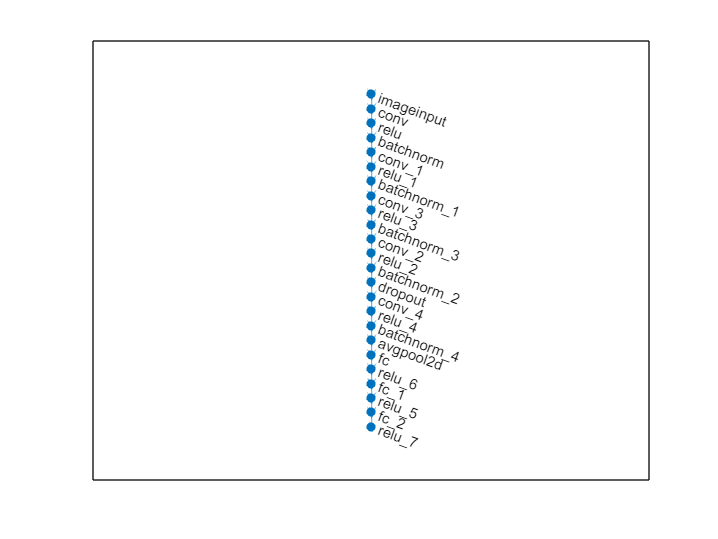

plot(layerGraph(layers));